# Covid classification - LSTM

remove previous data

close all; clc; clear;

load japaneseVowels pretraind network

load net_lstm_japaneseVowels

Create audioDatastore objects of the data and split it into train, validation and test sets

dataset_name = "all"; % choose dataset
shuffle_dataset = "no"; % choose if to shuffle the datasets

% load data
[adsTrain, adsVal, adsTest] = load_datasets(shuffle_dataset, dataset_name);

extract auto-segmentation results from yamnet model

% pre-processing - cough event indices
[FeaturesTrain, trueLabelsTrain, adsSpecsTrain] = preprocess_classification_lstm(adsTrain);

features extraction for segmentation done!!
segmentation done!!
features extraction for classification done!!


[FeaturesVal, trueLabelsVal, adsSpecsVal] = preprocess_classification_lstm(adsVal);

features extraction for segmentation done!!
segmentation done!!
features extraction for classification done!!


[FeaturesTest, trueLabelsTest, adsSpecsTest] = preprocess_classification_lstm(adsTest);

features extraction for segmentation done!!
segmentation done!!
features extraction for classification done!!


convert net_lstm_japaneseVowels to a [layerGraph](docid:nnet_ref#mw_399d64ed-680b-46f0-af77-0472ba1910d8), and then replace the final [fullyConnectedLayer](docid:nnet_ref#mw_1e7fbc56-4746-4f30-8cd9-7048ce806a0d) and the final [classificationLayer](docid:nnet_ref#bu5lho8) to reflect the new task.

uniqueLabels = unique(trueLabelsTrain);
numLabels = 2;
num_train_pos = sum(trueLabelsTrain == "positive");
num_train_neg = sum(trueLabelsTrain == "negative");
num_train = num_train_pos + num_train_neg;
classWeightsUniform = 'none';
classWeightsNonUniform = [num_train_pos, num_train_neg] / num_train;

classWeights = classWeightsNonUniform;

lgraph = layerGraph(net_lstm_japaneseVowels.Layers);

% newlstmlayer = lstmLayer(128, "Name", "lstm2", "OutputMode", "sequence");
% lgraph = replaceLayer(lgraph, "lstm2", newlstmlayer);
% 
% newlstmlayer = lstmLayer(128, "Name", "lstm3", "OutputMode", "last");
% lgraph = replaceLayer(lgraph, "lstm3", newlstmlayer);
% 
newDenseLayer = fullyConnectedLayer(32, "Name", "fc2");
lgraph = replaceLayer(lgraph, "fc2", newDenseLayer);

newDenseLayer = fullyConnectedLayer(numLabels, "Name", "fc3");
lgraph = replaceLayer(lgraph, "fc3", newDenseLayer);

newClassificationLayer = classificationLayer( ...
    "Name", "classification", ...
    "Classes", uniqueLabels, ...
    'ClassWeights', classWeights);
lgraph = replaceLayer(lgraph, "classification", newClassificationLayer);


% lgraph = removeLayers(lgraph, {'fc', 'softmax', 'classification'});
% 
% layers = [
%     fullyConnectedLayer(100, "Name", "fc1")
%     batchNormalizationLayer("Name", "bn")
%     reluLayer("Name", "relu")
%     fullyConnectedLayer(numLabels, "Name", "fc2")
%     softmaxLayer("Name", "softmax")
%     classificationLayer( ...
%         "Name", "classification", ...
%         "Classes", uniqueLabels, ...
%         'ClassWeights', classWeights)
%     ];
% 
% lgraph = addLayers(lgraph, layers);
% lgraph = connectLayers(lgraph,'lstm','fc1');
% 
% 
% lgraph.Layers(2, 1) = 'sequence';


% inputSize = 12;
% numHiddenUnits = 100;
% numClasses = 2;
% 
% layers = [ ...
%     sequenceInputLayer(inputSize)
%     lstmLayer(numHiddenUnits, 'OutputMode', 'last')
%     fullyConnectedLayer(numClasses)
%     softmaxLayer
%     classificationLayer("Name", "classification", "Classes", uniqueLabels, 'ClassWeights', classWeights) ...
%     ];

Specify the training options. Specify the solver as `'adam'` and `'GradientThreshold'` as 1. Set the mini-batch size to 27 and set the maximum number of epochs to 70.

Because the mini-batches are small with short sequences, the CPU is better suited for training. Set `'ExecutionEnvironment'` to `'cpu'`. To train on a GPU, if available, set `'ExecutionEnvironment'` to `'auto'` (the default value).

miniBatchSize = 64;
maxEpochs = 15;
InitialLearnRate = 0.01;
L2Regularization =0.0001;
validationFrequency = floor(numel(trueLabelsTrain)/miniBatchSize);

% options = trainingOptions('adam', ...
%     'MaxEpochs', maxEpochs, ...
%     'MiniBatchSize', miniBatchSize, ...
%     'GradientThreshold', 1, ...
%     'ValidationData', {FeaturesVal, trueLabelsVal}, ...
%     'ValidationFrequency', validationFrequency, ...
%     'Shuffle', 'every-epoch', ...
%     'Verbose',false, ...
%     'Plots','training-progress' ...
%     );

options = trainingOptions( ...
    'adam', ...
    'MaxEpochs', maxEpochs, ...
    'MiniBatchSize', miniBatchSize, ...
    'GradientThreshold', 1, ...
    'Verbose',true, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', {FeaturesVal, trueLabelsVal}, ...
    'ValidationFrequency', validationFrequency, ...
    'InitialLearnRate', InitialLearnRate, ...
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropPeriod', 10, ...
    'LearnRateDropFactor', 0.1, ...
    'L2Regularization', L2Regularization, ...
    'SequencePaddingDirection', 'right', ...
    'Plots', 'training-progress' ...
    );

Train the LSTM network with the specified training options.

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:02 |       40.62% |       44.09% |       0.3937 |       0.4286 |          0.0100 |
|       1 |          12 |       00:00:04 |       57.81% |       53.15% |       0.4069 |       0.3827 |          0.0100 |
|       2 |          24 |       00:00:05 |       35.94% |       45.67% |       0.3508 |       0.3419 |          0.0100 |
|       3 |          36 |       00:00:06 |       54.69% |       54.33% |       0.3301 |       0.3490 |          0.0100 |
|       

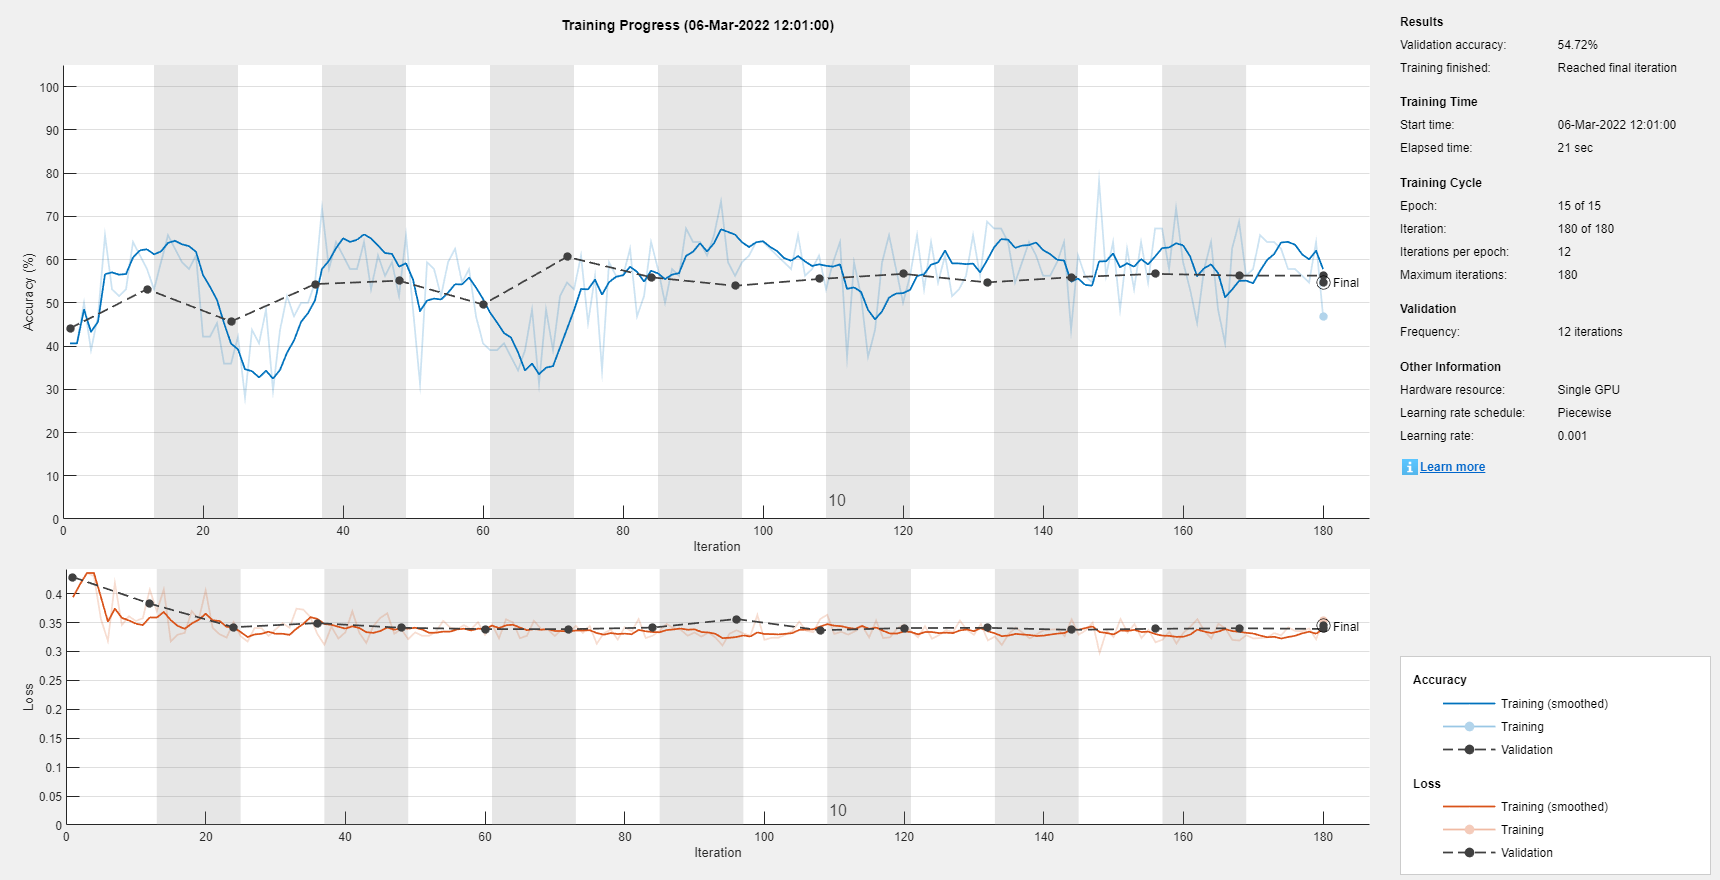

net_lstm = trainNetwork(FeaturesTrain, trueLabelsTrain, lgraph.Layers, options);

% analyzeNetwork(net_lstm);

predict on train, val and test sets (probability [0,1]).

predLabelsTrain = predict(net_lstm, FeaturesTrain, 'MiniBatchSize', miniBatchSize);
predLabelsTrain = predLabelsTrain(:, 2);
predLabelsVal   = predict(net_lstm, FeaturesVal, 'MiniBatchSize', miniBatchSize);
predLabelsVal   = predLabelsVal(:, 2);
predLabelsTest  = predict(net_lstm, FeaturesTest, 'MiniBatchSize', miniBatchSize);
predLabelsTest  = predLabelsTest(:, 2);

find best ROC thrshold on val set, and plot ROC curve

plot ROC curve and confusion matrix on test set.

display for train, val and test sets:

- ROC & AUC

- confusion matrix

- accuracy, UAR (unweighted average recall), F1 score, sensetivity, PPV, specificity

accuracy = (TP + TN) / (TP + TN + FP + FN)

UAR = (sensetivity + specificity) / 2

F1-score = 2 * (PPV * sensitivity) / (PPV + sensitivity)

sensitivity = TP / (TP + FN)

PPV = TP / (TP + FP)

specificity = TN / (TN + FP)

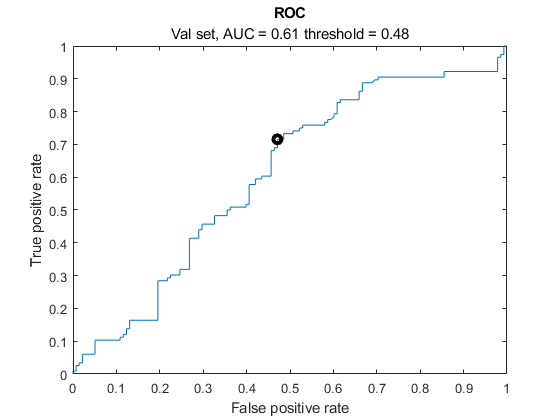

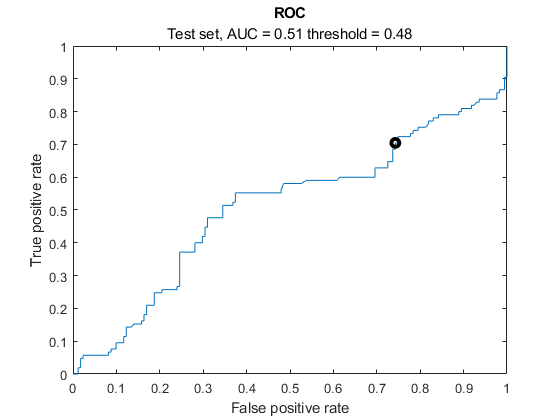

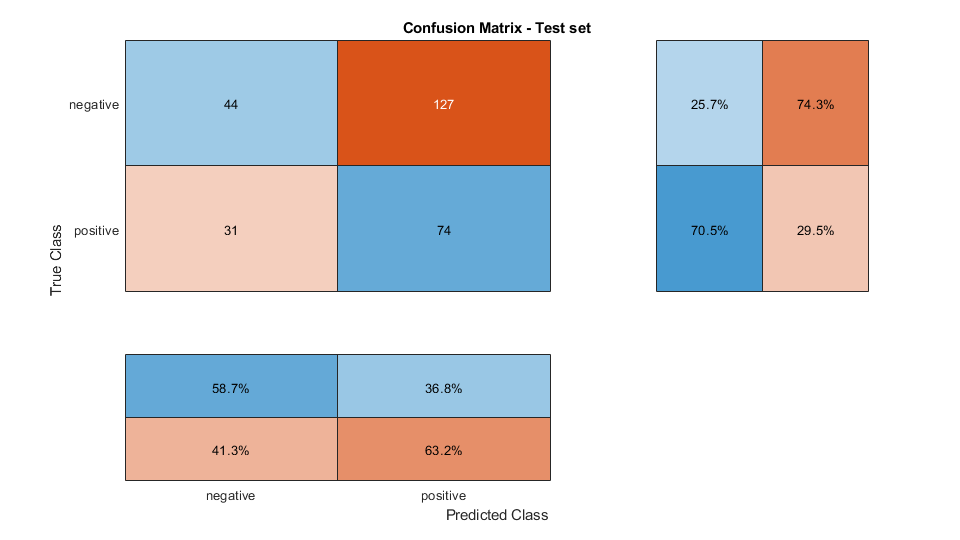

scores:
             accuracy [%]    UAR [%]    F1 [%]    sensitivity [%]    PPV [%]    specificity [%]
             ____________    _______    ______    _______________    _______    _______________

    train        45.7         48.7       48.8          64.2           39.4           33.2      
    val            61         61.9       62.6          71.6           55.7           52.2      
    test         42.8         48.1       48.4          70.5           36.8           25.7      



extract_scores_classification_lstm({predLabelsTrain predLabelsVal predLabelsTest}, {trueLabelsTrain trueLabelsVal trueLabelsTest});